# 02686 - Scientific Computing for Differential Equations - Exam 7 - ESDIRK23 Method 

## ESDIRK23 with Variable Step Size

mu = 3;
mu2 = 20;
x0 = [1.0;1.0];
N = 10000;

t0_1 = 0; tf_1 = mu*5; h_1 = (tf_1-t0_1)/N;
t0_2 = 0; tf_2 = mu2*5; h_2 = (tf_2-t0_2)/N;

abstol = 1e-7;
reltol = 1e-7;

[T,X,G,info,stats] = ESDIRK23(@VanderPolFun,@VanderPolJac,t0_1,tf_1,x0,h_1,abstol,reltol,mu);
[T1,X1,G1,info1,stats1] = ESDIRK23(@VanderPolFun,@VanderPolJac,t0_2,tf_2,x0,h_2,abstol,reltol,mu2);

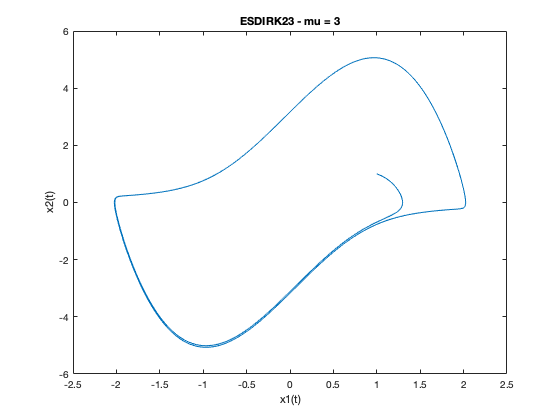

plot(X(:,1),X(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('ESDIRK23 - mu = 3')

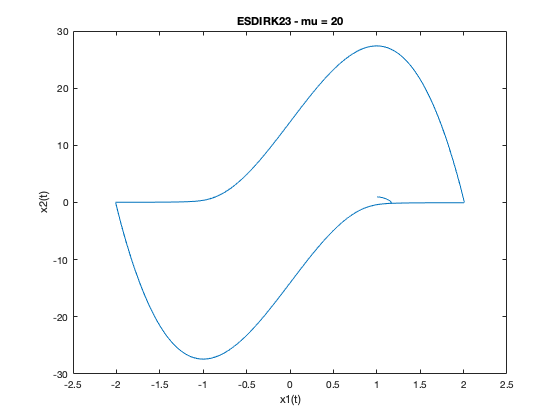

plot(X1(:,1),X1(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('ESDIRK23 - mu = 20')

## Solver ODE45

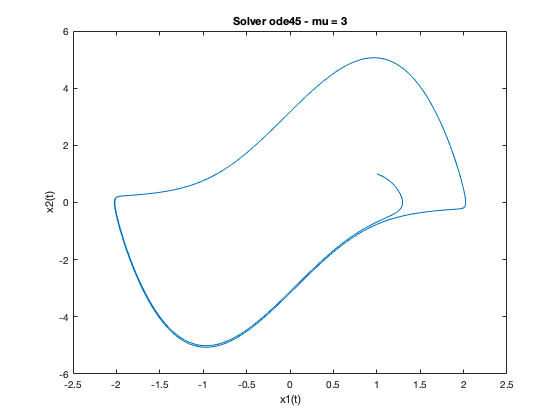

mu = 3;
x0 = [1.0; 1.0];
options = odeset('RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X]=ode45(@VanDerPol,[0 5*mu],x0,options,mu);

plot(X(:,1),X(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('Solver ode45 - mu = 3')

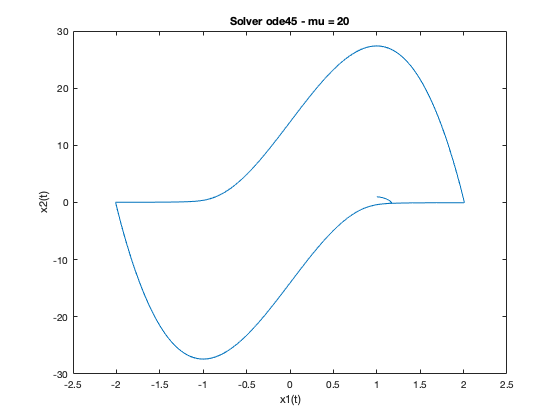

mu = 20;
x0 = [1.0; 1.0];
options = odeset('RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X]=ode45(@VanDerPol,[0 5*mu],x0,options,mu);

plot(X(:,1),X(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('Solver ode45 - mu = 20')

## Solver ODE15s

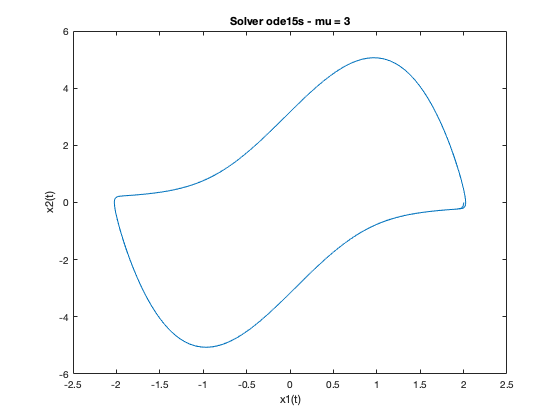

mu = 3;
x0 = [2.0; 0.0];
options = odeset('Jacobian',@JacVanDerPol,'RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X]=ode15s(@VanDerPol,[0 5*mu],x0,options,mu);

plot(X(:,1),X(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('Solver ode15s - mu = 3')

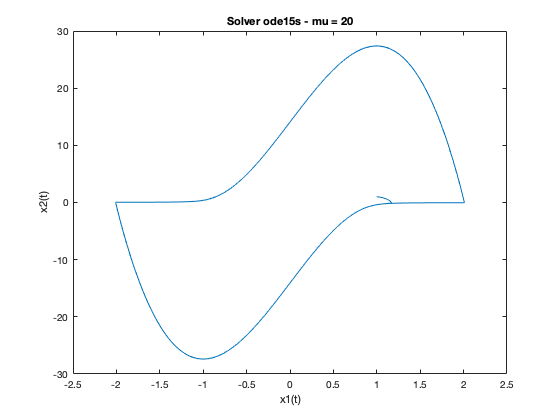

mu = 20;
x0 = [1.0; 1.0];
options = odeset('Jacobian',@JacVanDerPol,'RelTol',1.0e-6,'AbsTol',1.0e-6);
[T,X]=ode15s(@VanDerPol,[0 5*mu],x0,options,mu);

plot(X(:,1),X(:,2))
xlabel('x1(t)')
ylabel('x2(t)')
title('Solver ode15s - mu = 20')